# **Semantic priming**

## **Part 1. Temporal analysis **

***Data exploration***

load CIBA120_data.mat

Variables:

ep_cong_s1:

108x204x1001; 176432256  double

1001-time-point-long epochs (108 epochs) in 204 gradiometers. subject 1, congruent condition

ep_cong_s2

108x204x1001

1001-time-point-long epochs (108 epochs) in 204 gradiometers. subject 2, congruent condition

ep_incong_s1

108x204x1001

1001-time-point-long epochs (108 epochs) in 204 gradiometers. subject 1, incongruent condition

ep_incong_s2

108x204x1001; 176432256  double

1001-time-point-long epochs (108 epochs) in 204 gradiometers. subject 2, incongruent condition

inputNames

1x204

Names/numbers of the MEG gradiometers

time_points 1x1001

Timing of the epochs in milliseconds with respect to word onsets

### Data analysis

We can see the behavior of all epochs or average them to analyze the signal compared to the baseline (prestimulus time). This is mainly done to look for the representative hallmark at 400 ms and surrounding time points.

Average the first dimension (epochs) to visualize the signal of all 204 gradiometers

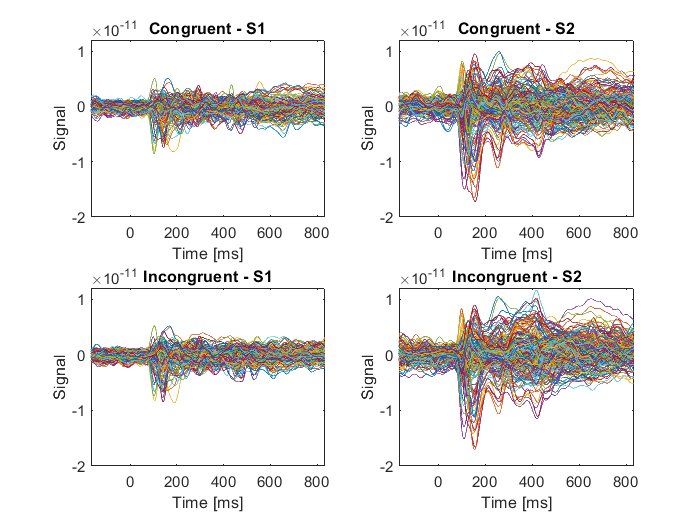

figure;
subplot(2,2,1)
plot(time_points, squeeze(mean(ep_cong_s1(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S1')

subplot(2,2,2)
plot(time_points, squeeze(mean(ep_cong_s2(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S2')


subplot(2,2,3)
plot(time_points, squeeze(mean(ep_incong_s1(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S1')

subplot(2,2,4)
plot(time_points, squeeze(mean(ep_incong_s2(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S2')

Calculating mean and standard deviation for each condition and subject

% Subject 1
meanc1 = squeeze(mean(mean(ep_cong_s1(1:108,:,:)),2)).';
meani1 = squeeze(mean(mean(ep_incong_s1(1:108,:,:)),2)).';
stdc1 = squeeze(std(mean(ep_cong_s1(1:108,:,:)))).';
stdi1 = squeeze(std(mean(ep_incong_s1(1:108,:,:)))).';

% Subject 2
meanc2 = squeeze(mean(mean(ep_cong_s2(1:108,:,:)),2)).';
meani2 = squeeze(mean(mean(ep_incong_s2(1:108,:,:)),2)).';
stdc2 = squeeze(std(mean(ep_cong_s2(1:108,:,:)))).';
stdi2 = squeeze(std(mean(ep_incong_s2(1:108,:,:)))).';


Plotting just the mean and the variance

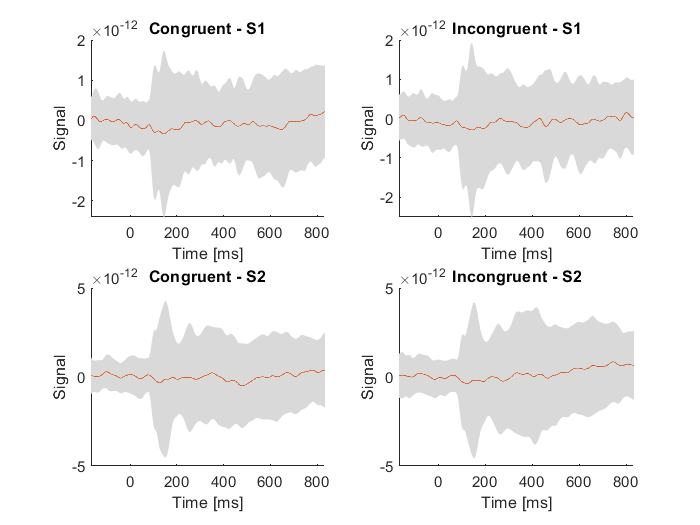

figure;
subplot(2,2,1)
hold on;
fill([time_points, fliplr(time_points)], [meanc1+stdc1, fliplr(meanc1-stdc1)], [0.85,0.85,0.85],'EdgeColor', 'none');
plot(time_points, meanc1)
%set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S1')

subplot(2,2,2)
hold on;
fill([time_points, fliplr(time_points)], [meani1+stdi1, fliplr(meani1-stdi1)], [0.85,0.85,0.85],'EdgeColor', 'none');
plot(time_points, meani1)
%set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S1')

subplot(2,2,3)
hold on;
fill([time_points, fliplr(time_points)], [meanc2+stdc2, fliplr(meanc2-stdc2)], [0.85,0.85,0.85],'EdgeColor', 'none');
plot(time_points, meanc2)
%set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S2')

subplot(2,2,4)
hold on;
fill([time_points, fliplr(time_points)], [meani2+stdi2, fliplr(meani2-stdi2)], [0.85,0.85,0.85],'EdgeColor', 'none');
plot(time_points, meani2)
%set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [-167,833])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S2')

hold off;

Zoom 80-500 ms

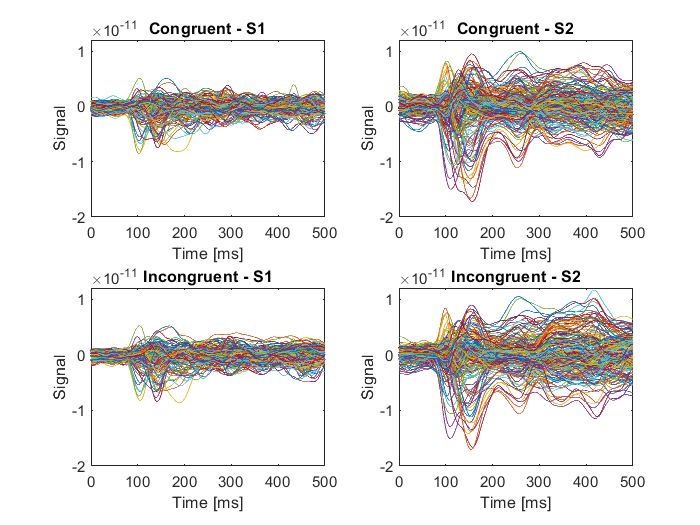

figure;
subplot(2,2,1)
plot(time_points, squeeze(mean(ep_cong_s1(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [0,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S1')

subplot(2,2,2)
plot(time_points, squeeze(mean(ep_cong_s2(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [0,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S2')


subplot(2,2,3)
plot(time_points, squeeze(mean(ep_incong_s1(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [0,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S1')

subplot(2,2,4)
plot(time_points, squeeze(mean(ep_incong_s2(1:108,:,:))))
set(gca, 'ylim', [-2*10^-11,1.2*10^-11])
set(gca, 'xlim', [0,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S2')

Zoom 350-450 ms

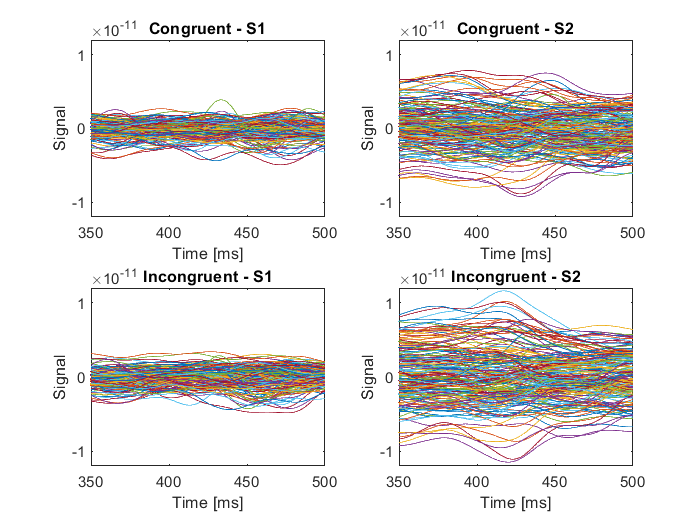

figure;
subplot(2,2,1)
plot(time_points, squeeze(mean(ep_cong_s1(1:108,:,:))))
set(gca, 'ylim', [-1.2*10^-11,1.2*10^-11])
set(gca, 'xlim', [350,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S1')

subplot(2,2,2)
plot(time_points, squeeze(mean(ep_cong_s2(1:108,:,:))))
set(gca, 'ylim', [-1.2*10^-11,1.2*10^-11])
set(gca, 'xlim', [350,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Congruent - S2')


subplot(2,2,3)
plot(time_points, squeeze(mean(ep_incong_s1(1:108,:,:))))
set(gca, 'ylim', [-1.2*10^-11,1.2*10^-11])
set(gca, 'xlim', [350,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S1')

subplot(2,2,4)
plot(time_points, squeeze(mean(ep_incong_s2(1:108,:,:))))
set(gca, 'ylim', [-1.2*10^-11,1.2*10^-11])
set(gca, 'xlim', [350,500])
xlabel('Time [ms]')
ylabel('Signal')
title('Incongruent - S2')
hold off

## **Part 1. Topography analysis **

We can identify troughs in certain intervals at around 90-115, 139-162, 240-260, 420-470. Therefore, we can compare the topograhy of the congruent and incongruent conditions for both subjects. Moreover, we can detect the sensors showing the effect of interest around these intervals by averaging

int_400 = find(time_points>300 & time_points<500);
int_3545 = find(time_points>350 & time_points<450);
int_450 = find(time_points>400 & time_points<480);

Since what we want is to detect the the average signal around the interval, we average across the 3rd dimension. The higher or the lower the value in the sensors will determine which show the representative peak or trough. We also need to average across the 1st dimension (epochs) because we are only interested in how strong the signal is in the different gradiometers. Important is to note that in the same intervals we can find not only troughs but peaks in some gradiometers. This suggests that the behaviour is not consistent along the cortex.

Interval around 400 (300-500)

% Subject 1
ave_data400c1 = squeeze(mean(mean(ep_cong_s1(:,:,int_400),3),1));
ave_data400i1 = squeeze(mean(mean(ep_incong_s1(:,:,int_400),3),1));
% Subject 2
ave_data400c2 = squeeze(mean(mean(ep_cong_s2(:,:,int_400),3),1));
ave_data400i2 = squeeze(mean(mean(ep_incong_s2(:,:,int_400),3),1));

Interval around 400 (350-450)

% Subject 1
ave_data3545c1 = squeeze(mean(mean(ep_cong_s1(:,:,int_3545),3),1));
ave_data3545i1 = squeeze(mean(mean(ep_incong_s1(:,:,int_3545),3),1));
% Subject 2
ave_data3545c2 = squeeze(mean(mean(ep_cong_s2(:,:,int_3545),3),1));
ave_data3545i2 = squeeze(mean(mean(ep_incong_s2(:,:,int_3545),3),1));

Interval around 450

% Subject 1
ave_data450c1 = squeeze(mean(mean(ep_cong_s1(:,:,int_450),3),1));
ave_data450i1 = squeeze(mean(mean(ep_incong_s1(:,:,int_450),3),1));
% Subject 2
ave_data450c2 = squeeze(mean(mean(ep_cong_s2(:,:,int_450),3),1));
ave_data450i2 = squeeze(mean(mean(ep_incong_s2(:,:,int_450),3),1));

Note that for visualizing the gradiometer data the fact that two orthogonal gradiometers are in the same location need to be condsidered.

This means that the two gradiometers need to be visualized separately or combined into one representations. Here, it may be useful to take the absolute value of the data as the deflection  direction (negative/positive) is somewhat artbitrary in the two gradiometers.

The **204 gradiometers** are organized such that **two orthogonal gradiometers** exist at the same physical location, resulting in **102 unique physical sensor locations**. The alternating indexing scheme reflects this pairing:

- Odd indices (`1, 3, 5, ...`) represent the **first gradiometer** at each location.

- Even indices (`2, 4, 6, ...`) represent the **second gradiometer** at the same location.

`ave_data` is a vector containing averaged data from all gradiometers.

Each gradiometer measures the magnetic field change at a specific location, and the data alternates between the two orthogonal gradiometers for each location:

- Odd indices (`1, 3, 5, ...`): First gradiometer in each location.

- Even indices (`2, 4, 6, ...`): Second gradiometer in each location.

% Interval around 400 (300-500)

    % Subject 1
ave_data400c1_2 = abs(ave_data400c1(1:2:end))'+abs(ave_data400c1(2:2:end))';
ave_data400i1_2 = abs(ave_data400i1(1:2:end))'+abs(ave_data400i1(2:2:end))';
    % Subject 2
ave_data400c2_2 = abs(ave_data400c2(1:2:end))'+abs(ave_data400c2(2:2:end))';
ave_data400i2_2 = abs(ave_data400i2(1:2:end))'+abs(ave_data400i2(2:2:end))';

% Interval around 400 (350-450)
% Subject 1
ave_data3545c1_2 = abs(ave_data3545c1(1:2:end))'+abs(ave_data3545c1(2:2:end))';
ave_data3545i1_2 = abs(ave_data3545i1(1:2:end))'+abs(ave_data3545i1(2:2:end))';
% Subject 2
ave_data3545c2_2 = abs(ave_data3545c2(1:2:end))'+abs(ave_data3545c2(2:2:end))';
ave_data3545i2_2 = abs(ave_data3545i2(1:2:end))'+abs(ave_data3545i2(2:2:end))';

% Interval around 450
% Subject 1
ave_data450c1_2 = abs(ave_data450c1(1:2:end))'+abs(ave_data450c1(2:2:end))';
ave_data450i1_2 = abs(ave_data450i1(1:2:end))'+abs(ave_data450i1(2:2:end))';
% Subject 2
ave_data450c2_2 = abs(ave_data450c2(1:2:end))'+abs(ave_data450c2(2:2:end))';
ave_data450i2_2 = abs(ave_data450i2(1:2:end))'+abs(ave_data450i2(2:2:end))';

Plotting the one-dimensional data (102x1: its 102 locations with the pairs of 204 gradiometers) can be done with circular representation of each location with the function: plot_topography_mod('all',ave_data2,false,'grad_loc.mat');

Interval around 400 (300-500)

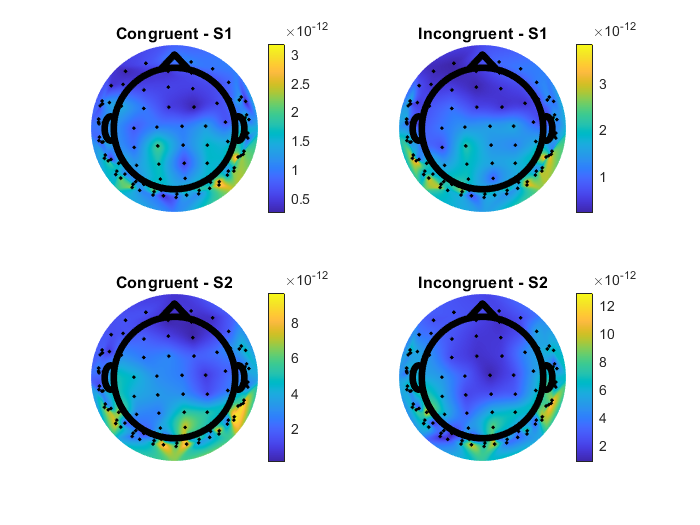

figure;
subplot(2,2,1)
plot_topography_mod('all',ave_data400c1_2,false,'grad_loc.mat');
title('Congruent - S1')

subplot(2,2,2)
plot_topography_mod('all',ave_data400i1_2,false,'grad_loc.mat');
title('Incongruent - S1')

subplot(2,2,3)
plot_topography_mod('all',ave_data400c2_2,false,'grad_loc.mat');
title('Congruent - S2')

subplot(2,2,4)
plot_topography_mod('all',ave_data400i2_2,false,'grad_loc.mat');
title('Incongruent - S2')

Interval around 400 (350-450)

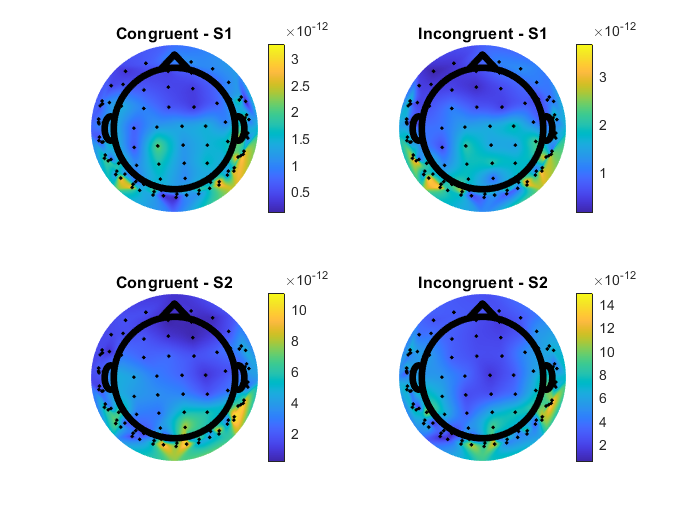

figure;
subplot(2,2,1)
plot_topography_mod('all',ave_data3545c1_2,false,'grad_loc.mat');
title('Congruent - S1')

subplot(2,2,2)
plot_topography_mod('all',ave_data3545i1_2,false,'grad_loc.mat');
title('Incongruent - S1')

subplot(2,2,3)
plot_topography_mod('all',ave_data3545c2_2,false,'grad_loc.mat');
title('Congruent - S2')

subplot(2,2,4)
plot_topography_mod('all',ave_data3545i2_2,false,'grad_loc.mat');
title('Incongruent - S2')

Interval around 450 (btw 400 and 480)

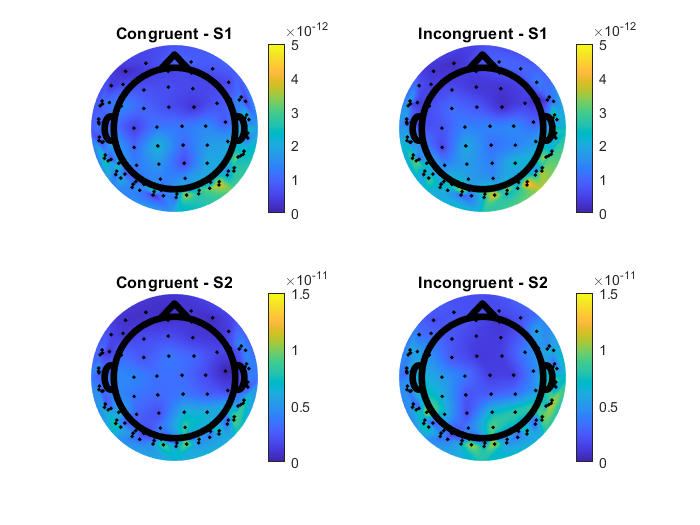

figure;
subplot(2,2,1)
plot_topography_mod('all',ave_data450c1_2,false,'grad_loc.mat');
title('Congruent - S1')
set(gca,'clim',[0 5]*1e-12)

subplot(2,2,2)
plot_topography_mod('all',ave_data450i1_2,false,'grad_loc.mat');
title('Incongruent - S1')
set(gca,'clim',[0 5]*1e-12)

subplot(2,2,3)
plot_topography_mod('all',ave_data450c2_2,false,'grad_loc.mat');
title('Congruent - S2')
set(gca,'clim',[0 15]*1e-12)

subplot(2,2,4)
plot_topography_mod('all',ave_data450i2_2,false,'grad_loc.mat');
title('Incongruent - S2')
set(gca,'clim',[0 15]*1e-12)

### **Plotting contrast for all the time windows and their two lowest sensors in the temporal domain**

The 5 sensors with the **lowest** signal will be picked (lowest because the N400 is negative). First, we can find the index. After, we can look for the index in the inputNames array.

%Around 400 (300-500)
[sortedc1400, sortidxc1400] = sort(ave_data400c1_2, 'ascend');
[sortedi1400, sortidxi1400] = sort(ave_data400i1_2, 'ascend');
[sortedc2400, sortidxc2400] = sort(ave_data400c2_2, 'ascend');
[sortedi2400, sortidxi2400] = sort(ave_data400i2_2, 'ascend');
c1sensoridx400=find(contains(inputNames,inputNames(sortidxc1400(1)))); % If you want the first 5 sensors, just add :5 to the indexing
i1sensoridx400=find(contains(inputNames,inputNames(sortidxi1400(1))));
c2sensoridx400=find(contains(inputNames,inputNames(sortidxc2400(1))));
i2sensoridx400=find(contains(inputNames,inputNames(sortidxi2400(1))));


%Around 400 (350-450)
[sortedc13545, sortidxc13545] = sort(ave_data3545c1_2, 'ascend');
[sortedi13545, sortidxi13545] = sort(ave_data3545i1_2, 'ascend');
[sortedc23545, sortidxc23545] = sort(ave_data3545c2_2, 'ascend');
[sortedi23545, sortidxi23545] = sort(ave_data3545i2_2, 'ascend');
c1sensoridx3545=find(contains(inputNames,inputNames(sortidxc13545(1)))); % If you want the first 5 sensors, just add :5 to the indexing
i1sensoridx3545=find(contains(inputNames,inputNames(sortidxi13545(1))));
c2sensoridx3545=find(contains(inputNames,inputNames(sortidxc23545(1))));
i2sensoridx3545=find(contains(inputNames,inputNames(sortidxi23545(1))));



%Around 450 (400-480)
[sortedc1, sortidxc1] = sort(ave_data450c1_2, 'ascend');
[sortedi1, sortidxi1] = sort(ave_data450i1_2, 'ascend');
[sortedc2, sortidxc2] = sort(ave_data450c2_2, 'ascend');
[sortedi2, sortidxi2] = sort(ave_data450i2_2, 'ascend');
c1sensoridx=find(contains(inputNames,inputNames(sortidxc1(1)))); % If you want the first 5 sensors, just add :5 to the indexing
i1sensoridx=find(contains(inputNames,inputNames(sortidxi1(1))));
c2sensoridx=find(contains(inputNames,inputNames(sortidxc2(1))));
i2sensoridx=find(contains(inputNames,inputNames(sortidxi2(1))));


Contrast congruent - incongruent

%Around 400 (300-500)
contrast1400 = ave_data400c1_2-ave_data400i1_2; % Subject 1
contrast2400 = ave_data400c2_2-ave_data400i2_2; % Subject 2

%Around 400 (350-450)
contrast13545 = ave_data3545c1_2-ave_data3545i1_2; % Subject 1
contrast23545 = ave_data3545c2_2-ave_data3545i2_2; % Subject 2

%Around 450 (400-480)
contrast1 = ave_data450c1_2-ave_data450i1_2; % Subject 1
contrast2 = ave_data450c2_2-ave_data450i2_2; % Subject 2

Subjects 1 and 2

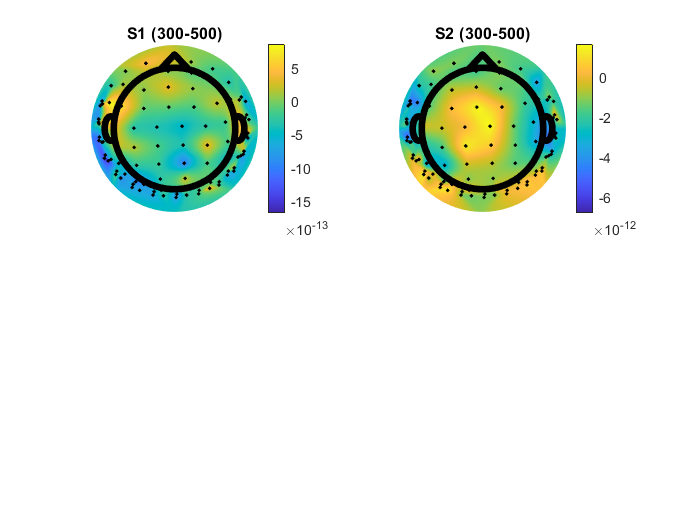

%Around 400 (300-500)
figure;
subplot(2,2,1)
plot_topography_mod('all',contrast1400,false,'grad_loc.mat');
title('S1 (300-500)')

subplot(2,2,2)
plot_topography_mod('all',contrast2400,false,'grad_loc.mat');
title('S2 (300-500)')

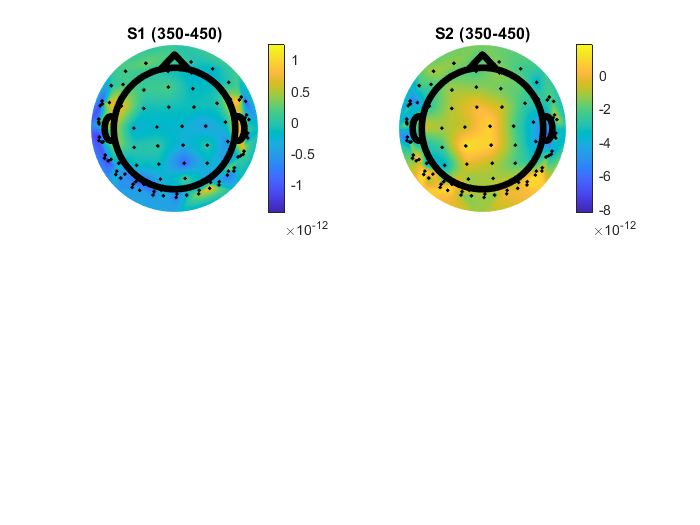


%Around 400 (350-450)
figure;
subplot(2,2,1)
plot_topography_mod('all',contrast13545,false,'grad_loc.mat');
title('S1 (350-450)')

subplot(2,2,2)
plot_topography_mod('all',contrast23545,false,'grad_loc.mat');
title('S2 (350-450)')

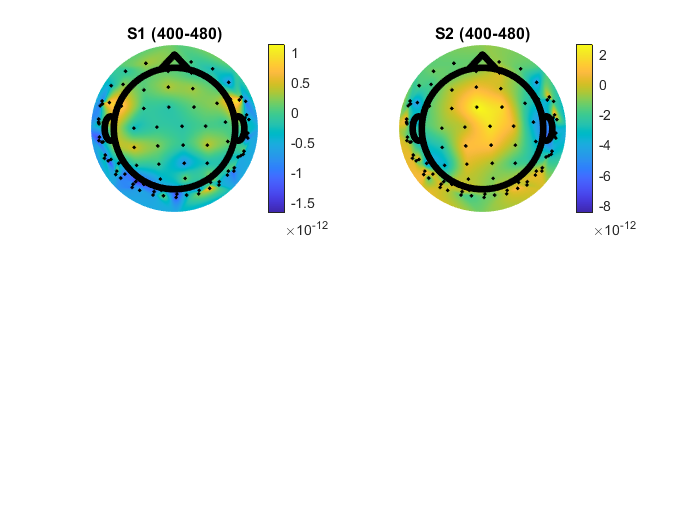


%Around 450 (400-480)
figure;
subplot(2,2,1)
plot_topography_mod('all',contrast1,false,'grad_loc.mat');
title('S1 (400-480)')

subplot(2,2,2)
plot_topography_mod('all',contrast2,false,'grad_loc.mat');
title('S2 (400-480)')

Time-series from two sensors can be visualized in the same plot with the help of the hold command. For example for the congruent and incongruent conditions

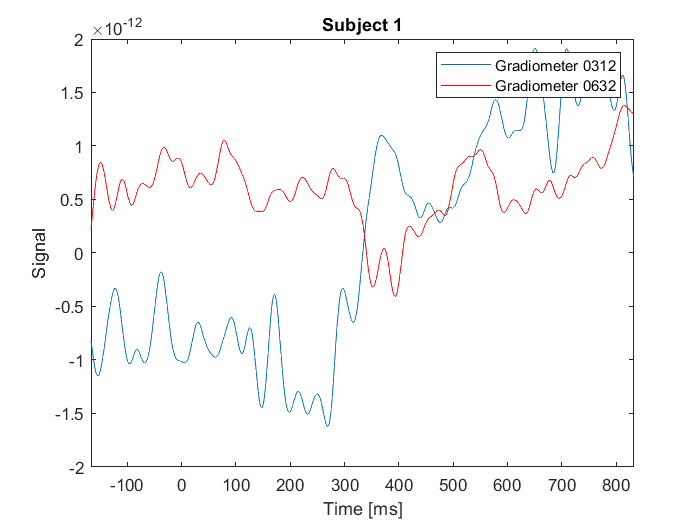

%Around 400 (300-500)
%Subject 1
figure;
plot(time_points,squeeze(mean(ep_cong_s1(:,c1sensoridx400,:))));
hold on
plot(time_points,squeeze(mean(ep_incong_s1(:,i1sensoridx400,:))),'r');
xlabel('Time [ms]')
legend(['Gradiometer ',inputNames{sortidxc1(1)}],['Gradiometer ',inputNames{sortidxi1(1)}]);
ylabel('Signal')
title('Subject 1')
set(gca, 'xlim', [-167,833])

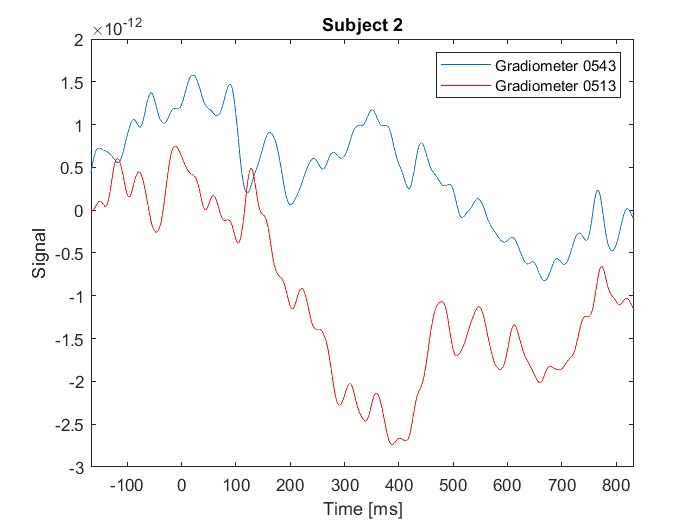


%Subject 2
figure;
plot(time_points,squeeze(mean(ep_cong_s2(:,c2sensoridx400,:))));
hold on
plot(time_points,squeeze(mean(ep_incong_s2(:,i2sensoridx400,:))),'r');
legend(['Gradiometer ',inputNames{sortidxc2(1)}],['Gradiometer ',inputNames{sortidxi2(1)}]);
xlabel('Time [ms]')
ylabel('Signal')
title('Subject 2')
set(gca, 'xlim', [-167,833])

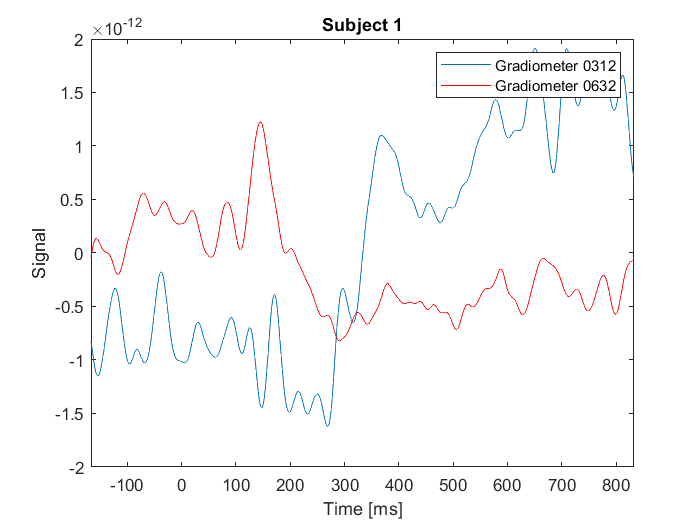



%Around 400 (350-450)
%Subject 1
figure;
plot(time_points,squeeze(mean(ep_cong_s1(:,c1sensoridx3545,:))));
hold on
plot(time_points,squeeze(mean(ep_incong_s1(:,i1sensoridx3545,:))),'r');
xlabel('Time [ms]')
legend(['Gradiometer ',inputNames{sortidxc1(1)}],['Gradiometer ',inputNames{sortidxi1(1)}]);
ylabel('Signal')
title('Subject 1')
set(gca, 'xlim', [-167,833])

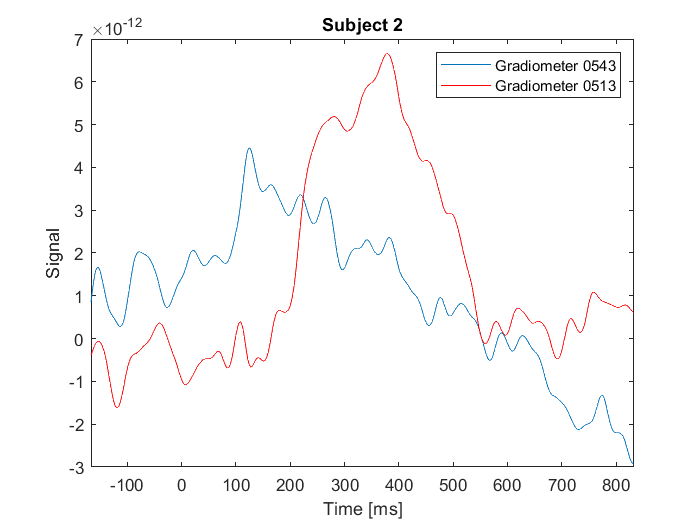


%Subject 2
figure;
plot(time_points,squeeze(mean(ep_cong_s2(:,c2sensoridx3545,:))));
hold on
plot(time_points,squeeze(mean(ep_incong_s2(:,i2sensoridx3545,:))),'r');
legend(['Gradiometer ',inputNames{sortidxc2(1)}],['Gradiometer ',inputNames{sortidxi2(1)}]);
xlabel('Time [ms]')
ylabel('Signal')
title('Subject 2')
set(gca, 'xlim', [-167,833])

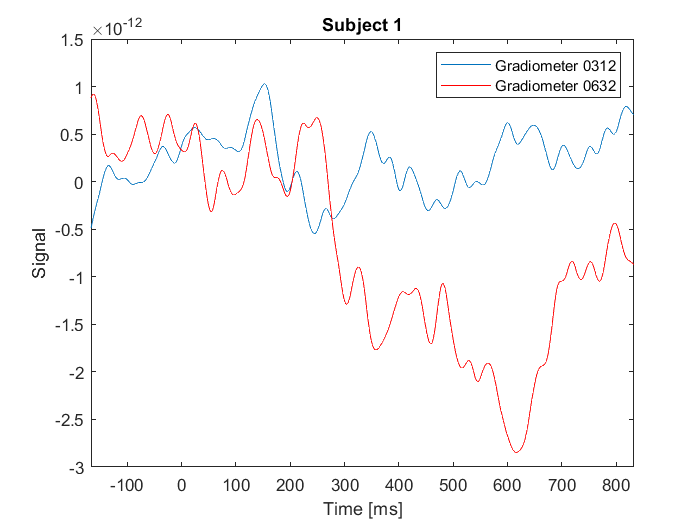






%Around 450 (400-480)
%Subject 1
figure;
plot(time_points,squeeze(mean(ep_cong_s1(:,c1sensoridx,:))));
hold on
plot(time_points,squeeze(mean(ep_incong_s1(:,i1sensoridx,:))),'r');
xlabel('Time [ms]')
legend(['Gradiometer ',inputNames{sortidxc1(1)}],['Gradiometer ',inputNames{sortidxi1(1)}]);
ylabel('Signal')
title('Subject 1')
set(gca, 'xlim', [-167,833])

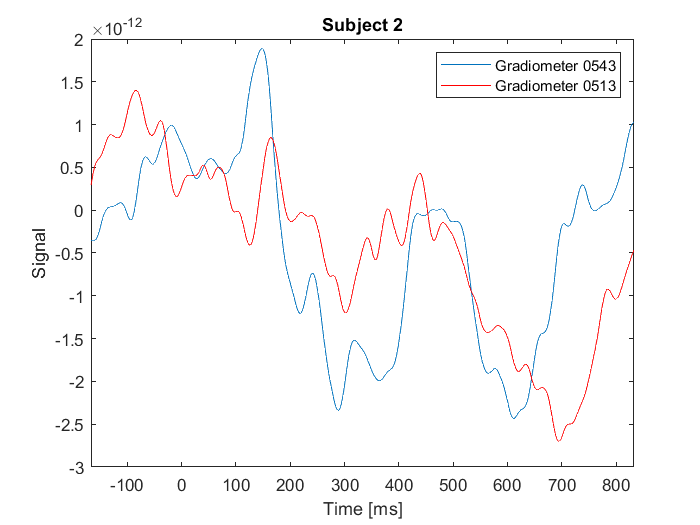


%Subject 2
figure;
plot(time_points,squeeze(mean(ep_cong_s2(:,c2sensoridx,:))));
hold on
plot(time_points,squeeze(mean(ep_incong_s2(:,i2sensoridx,:))),'r');
legend(['Gradiometer ',inputNames{sortidxc2(1)}],['Gradiometer ',inputNames{sortidxi2(1)}]);
xlabel('Time [ms]')
ylabel('Signal')
title('Subject 2')
set(gca, 'xlim', [-167,833])

## Comparing before and after break

Topography analysis

% Subject 1
ave_cbefrest1 = squeeze(mean(mean(ep_cong_s1(1:54,:,int_400),3),1));
ave_ibefrest1 = squeeze(mean(mean(ep_incong_s1(1:54,:,int_400),3),1));
ave_cafrest1 = squeeze(mean(mean(ep_cong_s2(55:108,:,int_400),3),1));
ave_iafrest1 = squeeze(mean(mean(ep_incong_s2(55:108,:,int_400),3),1));
% Subject 2
ave_cbefrest2 = squeeze(mean(mean(ep_cong_s2(1:54,:,int_400),3),1));
ave_ibefrest2 = squeeze(mean(mean(ep_incong_s2(1:54,:,int_400),3),1));
ave_cafrest2 = squeeze(mean(mean(ep_cong_s2(55:108,:,int_400),3),1));
ave_iafrest2 = squeeze(mean(mean(ep_incong_s2(55:108,:,int_400),3),1));

% Fixing for orthogonal gradiometers
    % Subject 1
ave_cbefrest1_2 = abs(ave_cbefrest1(1:2:end))'+abs(ave_cbefrest1(2:2:end))';
ave_ibefrest1_2 = abs(ave_ibefrest1(1:2:end))'+abs(ave_ibefrest1(2:2:end))';
ave_cafrest1_2 = abs(ave_cafrest1(1:2:end))'+abs(ave_cafrest1(2:2:end))';
ave_iafrest1_2 = abs(ave_iafrest1(1:2:end))'+abs(ave_iafrest1(2:2:end))';
    % Subject 2
ave_cbefrest2_2 = abs(ave_cbefrest2(1:2:end))'+abs(ave_cbefrest2(2:2:end))';
ave_ibefrest2_2 = abs(ave_ibefrest2(1:2:end))'+abs(ave_ibefrest2(2:2:end))';
ave_cafrest2_2 = abs(ave_cafrest2(1:2:end))'+abs(ave_cafrest2(2:2:end))';
ave_iafrest2_2 = abs(ave_iafrest2(1:2:end))'+abs(ave_iafrest2(2:2:end))';

% Subject 1
contrast13545bef = ave_cbefrest1_2-ave_ibefrest1_2; % After rest
contrast13545af = ave_cafrest1_2-ave_iafrest1_2; % Before rest

% Subject 2
contrast23545bef = ave_cbefrest2_2-ave_ibefrest2_2; % After rest
contrast23545af = ave_cafrest2_2-ave_iafrest2_2; % Before rest

Subject 1

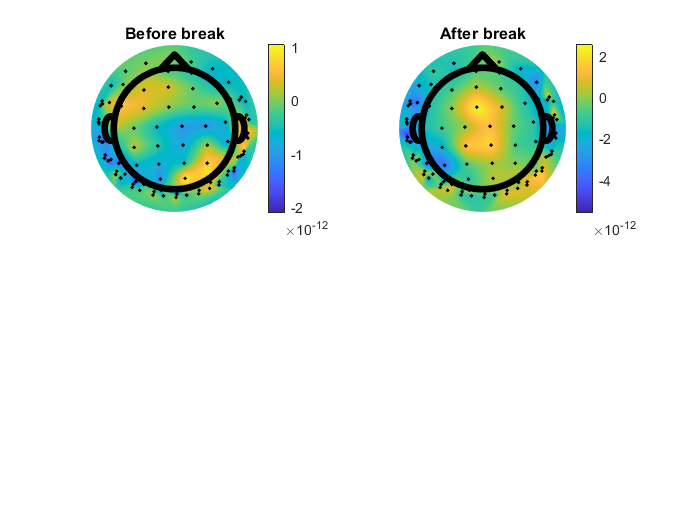


figure;
subplot(2,2,1)
plot_topography_mod('all',contrast13545bef,false,'grad_loc.mat');
title('Before break')
hold on
subplot(2,2,2)
plot_topography_mod('all',contrast13545af,false,'grad_loc.mat');
title('After break')

Subject 2

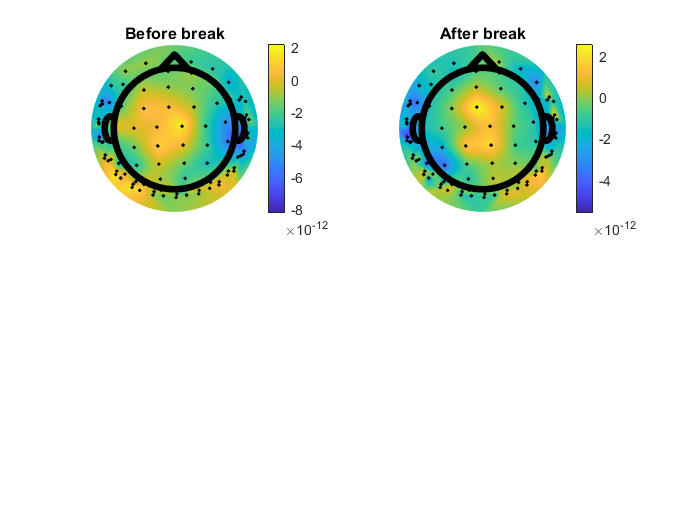

figure;
subplot(2,2,1)
plot_topography_mod('all',contrast23545bef,false,'grad_loc.mat');
title('Before break')
hold on
subplot(2,2,2)
plot_topography_mod('all',contrast23545af,false,'grad_loc.mat');
title('After break')